# Fuel Economy Analysis - SVM

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the data.

carData = readtable("./data/carEcon.xlsx", Sheet="carData");
carTest = readtable("./data/carEcon.xlsx", Sheet="carTest");
carTrain = readtable("./data/carEcon.xlsx", Sheet="carTrain");
whos carData carTrain carTest

  Name            Size             Bytes  Class    Attributes

  carData       600x15            380315  table              
  carTest       192x15            124705  table              
  carTrain      408x15            259725  table              



## Tasks 1 and 2 - Fit the model

Fit a model and evaluate at test values.

The table `carData` has been split into a training set `carTrain` and a test set `carTest`. The response variable is `"FuelEcon"`.

Notice that the fit is particularly poor. This can happen when predictors have different scales. Standardizing the data before fitting can improve the quality of the fit.

mdl = fitrsvm(carTrain, "FuelEcon", "KernelFunction", "polynomial",...
    "Standardize", true);

mdlLoss = loss(mdl, carTest)

mdlLoss = 0.9912

econPred = predict(mdl, carTest);

Plot the results.

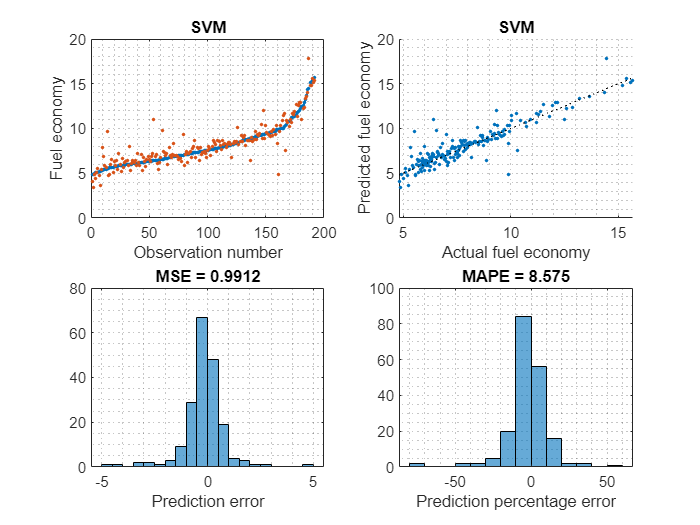

evaluateFit(carTest.FuelEcon, econPred, "SVM")

function evaluateFit(y, ypred, name)
    figure
    % Plot against observation number
    subplot(2,2,1)
    plot(y,'.')
    grid minor
    hold on
    plot(ypred,'.')
    hold off
    title(name)
    xlabel('Observation number')
    ylabel('Fuel economy')
    
    % Plot predicted and actual against each other
    subplot(2,2,2)
    scatter(y,ypred,'.')
    grid minor
    % Add 45-degree line
    xl = xlim;
    hold on
    plot(xl,xl,'k:')
    hold off
    title(name)
    xlabel('Actual fuel economy')
    ylabel('Predicted fuel economy')
    
    % Distribution of errors
    subplot(2,2,3)
    err = y-ypred;
    MSE = mean(err.^2,'omitnan');
    histogram(err)
    grid minor    
    title(['MSE = ',num2str(MSE,4)])
    xlabel('Prediction error')
    
    % Distribution of percentage errors
    subplot(2,2,4)
    err = 100*err./y;
    MAPE = mean(abs(err),'omitnan');
    histogram(err)
    grid minor
    title(['MAPE = ',num2str(MAPE,4)])
    xlabel('Prediction percentage error')
end
